% Define symbolic variables
syms x y lambda

% Define the quadratic objective function
f = x^2/40 + (3*x*y)/100 + y^2/20 - 5;

% Define the quadratic constraint function
g = x^2/4 + y^2/16 - 10;

% Define the Lagrange function
L = f - lambda * g;

% Calculate the gradients
gradL = gradient(L, [x, y, lambda]);

% Solve the system of equations
solution = solve(gradL == 0, [x, y, lambda]);





% Plot the ellipse
ezplot(f, [-20, 20, -20, 20]);
hold on;

% Plot x and y axes
plot([-20, 20], [0, 0], 'k--'); % x-axis
plot([0, 0], [-20, 20], 'k--'); % y-axis

% Set axis limits and labels
axis equal;
xlabel('x');
ylabel('y');

title('Plot of the Ellipse (f = 0)');

% Add a legend
legend('Ellipse', 'x-axis', 'y-axis');
grid on;
hold off;



% Calculate partial derivatives with respect to x and y
df_dx = diff(f, x);
df_dy = diff(f, y);

% Solve for critical points
critical_points = solve([df_dx == 0, df_dy == 0], [x, y]);


% Check if critical_points is empty or not a structure
if ~isempty(critical_points) && isstruct(critical_points) && isfield(critical_points, 'x') && isfield(critical_points, 'y')


    % Evaluate f at the critical points
    for i = 1:numel(critical_points.x)
        x_value = critical_points.x(i);
        y_value = critical_points.y(i);
        f_value = subs(f, [x, y], [x_value, y_value]);
        fprintf('Critical Point %d: (x = %f, y = %f) - f(x, y) = %f\n', i, x_value, y_value, f_value);
    end
else
    disp('No critical points found.');
end

Critical Point 1: (x = 0.000000, y = 0.000000) - f(x, y) = -5.000000




% Convert symbolic expression to function handle
f_func = matlabFunction(f);

% Create a grid of x and y values
[xGrid, yGrid] = meshgrid(-20:1:20, -20:1:20); % Adjust the range as needed

% Evaluate function
zValues = f_func(xGrid, yGrid);

% Create surface plot
surf(xGrid, yGrid, zValues)

% Labels and title
xlabel('x')
ylabel('y')
zlabel('f(x, y)')
title('Surface plot of f(x, y)')

% Adding zoom out feature
% You can use the zoom function in MATLAB. Here's an example of how to enable it:
zoom on; % This enables zooming with the mouse




ezplot(g, [-20, 20, -20, 20]);
hold on;

% Plot x and y axes
plot([-20, 20], [0, 0], 'k--'); % x-axis
plot([0, 0], [-20, 20], 'k--'); % y-axis

% Set axis limits and labels
axis equal;
xlabel('x');
ylabel('y');

title('Plot of the Ellipse (g = 0)');

% Add a legend
legend('Ellipse', 'x-axis', 'y-axis');
grid on;
hold off;

% Calculate partial derivatives with respect to x and y
dg_dx = diff(g, x);
dg_dy = diff(g, y);

% Solve for critical points
critical_points = solve([dg_dx == 0, dg_dy == 0], [x, y]);


% Check if critical_points is empty or not a structure
if ~isempty(critical_points) && isstruct(critical_points) && isfield(critical_points, 'x') && isfield(critical_points, 'y')


    % Evaluate f at the critical points
    for i = 1:numel(critical_points.x)
        x_value = critical_points.x(i);
        y_value = critical_points.y(i);
        g_value = subs(g, [x, y], [x_value, y_value]);
        fprintf('Critical Point %d: (x = %f, y = %f) - g(x, y) = %f\n', i, x_value, y_value, f_value);
    end
else
    disp('No critical points found.');
end

Critical Point 1: (x = 0.000000, y = 0.000000) - g(x, y) = -5.000000



% Convert symbolic expression to function handle
g_func = matlabFunction(g);

% Create a grid of x and y values
[xGrid, yGrid] = meshgrid(-20:1:20, -20:1:20); % Adjust the range as needed

% Evaluate function
zValues2 = g_func(xGrid, yGrid);

% Create surface plot
surf(xGrid, yGrid, zValues2)

% Labels and title
xlabel('x')
ylabel('y')
zlabel('g(x, y)')
title('Surface plot of g(x, y)')

% Adding zoom out feature
% You can use the zoom function in MATLAB. Here's an example of how to enable it:
zoom on; % This enables

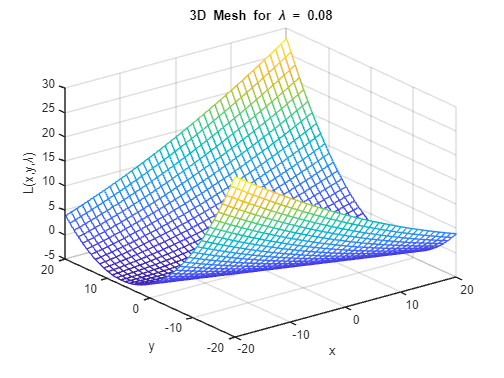

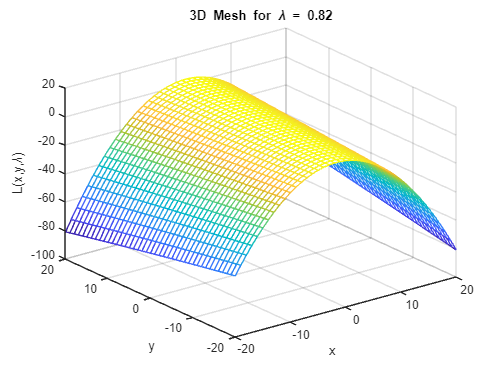

% Solve the system of equations
solution = solve(gradL == 0, [x, y, lambda]);

% Extract lambda solutions
lambda_solutions = eval(solution.lambda);

% Plot 3D mesh for each lambda solution
for i = 1:length(lambda_solutions)
    lambda_i = lambda_solutions(i);

    % Substituting the solution lambda in the Lagrange function
    L_sub = subs(L, lambda, lambda_i);

    % Define a range for x and y
    [X, Y] = meshgrid(-20:1:20, -20:1:20);

    % Evaluate Z over the grid
    Z = double(subs(L_sub, [x, y], {X, Y}));

    % Plotting
    figure;
    mesh(X, Y, Z);
    title(['3D Mesh for \lambda = ', num2str(lambda_i)]);
    xlabel('x');
    ylabel('y');
    zlabel('L(x,y,\lambda)');
end

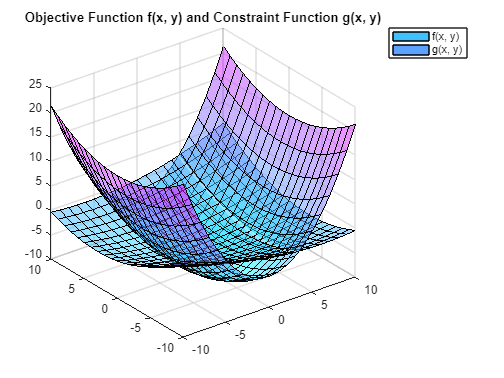

% Define a grid of values for x and y
[x_values, y_values] = meshgrid(-10:1:10, -10:1:10);

% Calculate the corresponding values of f and g for each (x, y) pair
f_values = double(subs(f, {x, y}, {x_values, y_values}));
g_values = double(subs(g, {x, y}, {x_values, y_values}));

% Create a 3D surf plot for the objective function f with a specific color map
figure;
surf(x_values, y_values, f_values, 'FaceAlpha', 0.5);
colormap('jet'); % First colormap, e.g., 'jet'

hold on;

% Create a 3D surf plot for the constraint function g with a different color map
surf(x_values, y_values, g_values, 'FaceAlpha', 0.5);
colormap('cool'); % Second contrasting colormap, e.g., 'cool'

title('Objective Function f(x, y) and Constraint Function g(x, y)');
legend('f(x, y)', 'g(x, y)');

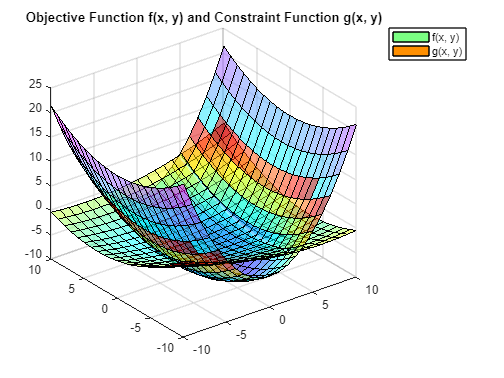

% Define a grid of values for x and y
[x_values, y_values] = meshgrid(-10:1:10, -10:1:10);

% Calculate the corresponding values of f and g for each (x, y) pair
f_values = double(subs(f, {x, y}, {x_values, y_values}));
g_values = double(subs(g, {x, y}, {x_values, y_values}));

% Create a figure
figure;

% Create a 3D surf plot for the objective function f
f_surf = surf(x_values, y_values, f_values, 'FaceAlpha', 0.5);
hold on;

% Adjust color of f_surf using its CData property
f_surf.CData = f_surf.ZData;
f_surf.CDataMapping = 'scaled';
colormap('jet'); % Use the 'jet' colormap for f

% Create a 3D surf plot for the constraint function g
g_surf = surf(x_values, y_values, g_values, 'FaceAlpha', 0.5);

% Adjust color of g_surf independently using its CData property
g_surf.CData = g_surf.ZData;
g_surf.CDataMapping = 'scaled';
colormap('cool'); % Attempt to set a different colormap for g

% Adjust global colormap to mix both color maps
colormap([jet; cool]);

title('Objective Function f(x, y) and Constraint Function g(x, y)');
legend('f(x, y)', 'g(x, y)');


% Define a grid of values for x and y
[x_values, y_values] = meshgrid(-20:1:20, -20:1:20);

% Calculate the corresponding values of f and g for each (x, y) pair
f_values = double(subs(f, {x, y}, {x_values, y_values}));
g_values = double(subs(g, {x, y}, {x_values, y_values}));

% Create a figure for all plots
figure;

% Plot the objective function f
f_surf = surf(x_values, y_values, f_values, 'FaceAlpha', 0.5, 'EdgeColor', 'none');
colormap('jet'); % Use a colormap for f
hold on;

% Plot the constraint function g
%g_surf = surf(x_values, y_values, g_values, 'FaceAlpha', 0.5, 'EdgeColor', 'none');
%colormap('cool'); % Use a different colormap for g







% Solve for lambda in the gradient of Lagrange function
solution = solve(gradL == 0, [x, y, lambda]);

% Extract x, y, and lambda solutions
x_solutions = eval(solution.x);
y_solutions = eval(solution.y);
lambda_solutions = eval(solution.lambda);
lambda_solutions_2 = lambda_solutions([1,3])

lambda_solutions_2 =     0.0800
    0.8200


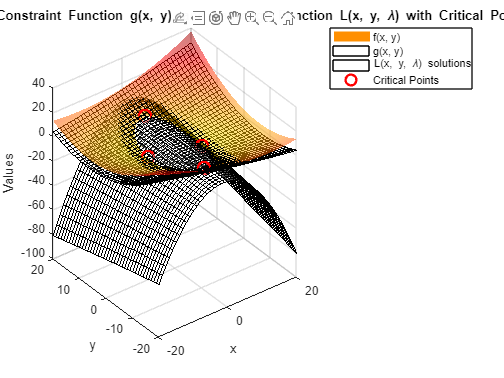

% Plot 3D mesh for each lambda solution
for i = 1:length(lambda_solutions_2)
    lambda_i = lambda_solutions_2(i);

    % Substituting the solution lambda in the Lagrange function
    L_sub = subs(L, lambda, lambda_i);

    % Evaluate Z over the grid
    Z = double(subs(L_sub, [x, y], {x_values, y_values}));

    % Plotting each lambda solution
    mesh(x_values, y_values, Z, 'EdgeColor', 'k', 'FaceAlpha', 0.3);
end

% Plot critical points
plot3(x_solutions, y_solutions, double(subs(f, {x, y}, {x_solutions, y_solutions})), 'ro', 'MarkerSize', 10, 'LineWidth', 2);

% Adjusting the plot
title('Objective Function f(x, y), Constraint Function g(x, y), and Lagrange Function L(x, y, \lambda) with Critical Points');
legend('f(x, y)', 'g(x, y)', 'L(x, y, \lambda) solutions', 'Critical Points');
xlabel('x');
ylabel('y');
zlabel('Values');

% Hold off to finalize the plot
hold off;



% Your existing symbolic expressions for f, g, and L (Lagrange function)
% f = ... (your definition of f)
% g = ... (your definition of g)
% L = ... (your definition of L)

% Define a grid of values for x and y
[x_values, y_values] = meshgrid(-20:1:20, -20:1:20);

% Calculate the corresponding values of f and g for each (x, y) pair
f_values = double(subs(f, {x, y}, {x_values, y_values}));
g_values = double(subs(g, {x, y}, {x_values, y_values}));

% Create a figure for all plots
figure;

% Plot the objective function f
f_surf = surf(x_values, y_values, f_values, 'FaceAlpha', 0.6, 'EdgeColor', 'none');
colormap('jet'); % Use a colormap for f
hold on;

% Plot the constraint function g
g_surf = surf(x_values, y_values, g_values, 'FaceAlpha', 0.6, 'EdgeColor', 'none');

% Plot contour for g = 0
[~, g_contour] = contour(x_values, y_values, g_values, [0, 0], 'k', 'LineWidth', 2);

% Solve for lambda in the gradient of Lagrange function
solution = solve(gradL == 0, [x, y, lambda]);

% Extract lambda solutions
lambda_solutions = eval(solution.lambda);
lambda_solutions_2 = lambda_solutions([1,3])

lambda_solutions_2 =     0.0800
    0.8200


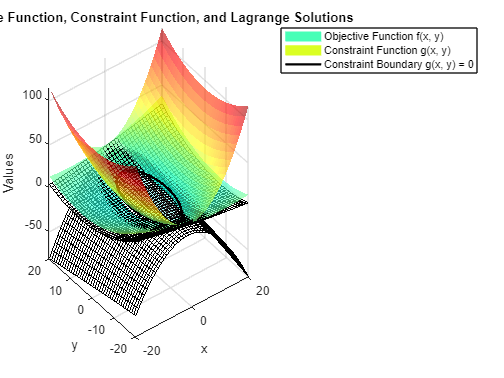

% Plot 3D mesh for each lambda solution
for i = 1:length(lambda_solutions_2)
    lambda_i = lambda_solutions_2(i);

    % Substituting the solution lambda in the Lagrange function
    L_sub = subs(L, lambda, lambda_i);

    % Evaluate Z over the grid
    Z = double(subs(L_sub, [x, y], {x_values, y_values}));

    % Plotting each lambda solution
    mesh(x_values, y_values, Z, 'EdgeColor', 'k', 'FaceAlpha', 0.3);
end

% Adjusting the plot
title('Objective Function, Constraint Function, and Lagrange Solutions');
legend([f_surf, g_surf, g_contour,], 'Objective Function f(x, y)', 'Constraint Function g(x, y)', 'Constraint Boundary g(x, y) = 0');
xlabel('x');
ylabel('y');
zlabel('Values');

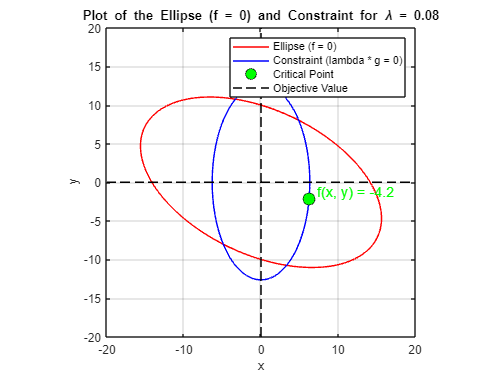

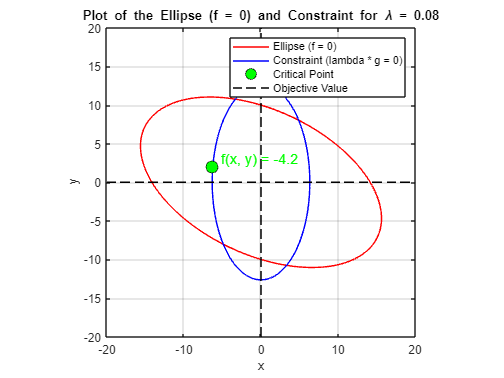

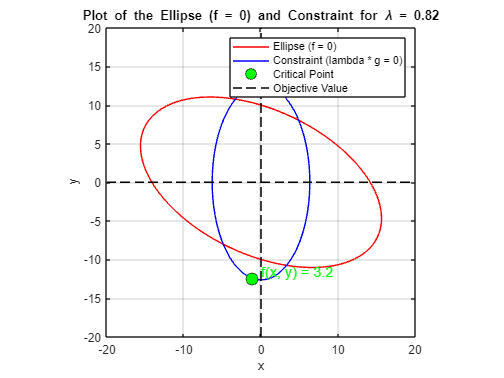

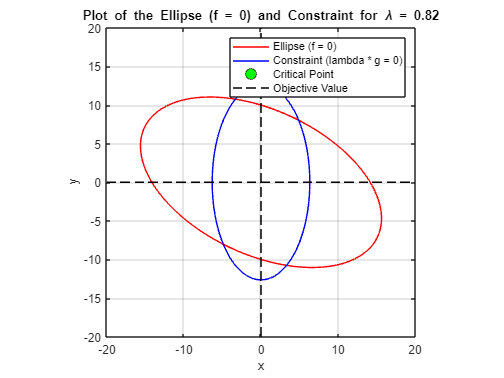

% Extract solutions and plot for each
for i = 1:length(solution.x)
    plotEllipseAndConstraint(f,g,solution.x(i), solution.y(i), solution.lambda(i));
end





% Loop through each critical point
for i = 1:numel(solution.x)
    x_val = double(solution.x(i));
    y_val = double(solution.y(i));
    lambda_val = double(solution.lambda(i));
    
    % Calculate the first derivative of the constraint function g
    dg_dx = diff(g, x);
    dg_dy = diff(g, y);
    
    % Calculate the first derivative values of g at the critical point
    dg_dx_val = subs(dg_dx, {x, y}, {x_val, y_val});
    dg_dy_val = subs(dg_dy, {x, y}, {x_val, y_val});
    
    % Calculate the first partial derivatives
    df_dx = diff(L, x);
    df_dy = diff(L, y);
    df_dlambda = diff(L, lambda);
    
    % Calculate the first derivative values at the critical point
    df_dx_val = subs(df_dx, {x, y, lambda}, {x_val, y_val, lambda_val});
    df_dy_val = subs(df_dy, {x, y, lambda}, {x_val, y_val, lambda_val});
    df_dlambda_val = subs(df_dlambda, {x, y, lambda}, {x_val, y_val, lambda_val});
    
    d2f_dx2 = diff(diff(L, x), x);
    d2f_dy2 = diff(diff(L, y), y);
    d2f_dxdy = diff(diff(L, x), y);
    
    d2f_dx2_val = subs(d2f_dx2, {x, y, lambda}, {x_val, y_val,lambda_val});
    d2f_dy2_val = subs(d2f_dy2, {x, y, lambda}, {x_val, y_val,lambda_val});
    d2f_dxdy_val = subs(d2f_dxdy, {x, y,lambda}, {x_val, y_val,lambda_val});
    
    % Calculate the discriminant for the second partial derivatives test
    discriminant = d2f_dx2_val * d2f_dy2_val - d2f_dxdy_val^2;
    
    disp(lambda_val)
    % Call the printCriticalPoint function to display information
    printCriticalPoint(i, x_val, y_val, lambda_val, dg_dx_val, dg_dy_val, df_dx_val, df_dy_val, df_dlambda_val, d2f_dx2_val, d2f_dy2_val, d2f_dxdy_val, discriminant);
end

    0.0800



Critical Point 1
x = 6.2385
y = -2.0795
lambda = 0.08
First Derivative dg/dx = (6*10^(1/2)*37^(1/2))/37
First Derivative dg/dy = -(10^(1/2)*37^(1/2))/74
First Derivative df/dx = 0
First Derivative df/dy = 0
First Derivative df/dlambda = 0
Second Derivative df/dx^2 = 1/100
Second Derivative df/dy^2 = 9/100
Second Derivative df/dxdy = 3/100
The second partial derivatives test is inconclusive.
------------------------


    0.0800



Critical Point 2
x = -6.2385
y = 2.0795
lambda = 0.08
First Derivative dg/dx = -(6*10^(1/2)*37^(1/2))/37
First Derivative dg/dy = (10^(1/2)*37^(1/2))/74
First Derivative df/dx = 0
First Derivative df/dy = 0
First Derivative df/dlambda = 0
Second Derivative df/dx^2 = 1/100
Second Derivative df/dy^2 = 9/100
Second Derivative df/dxdy = 3/100
The second partial derivatives test is inconclusive.
------------------------


    0.8200



Critical Point 3
x = -1.0398
y = -12.477
lambda = 0.82
First Derivative dg/dx = -(10^(1/2)*37^(1/2))/37
First Derivative dg/dy = -(3*10^(1/2)*37^(1/2))/37
First Derivative df/dx = 0
First Derivative df/dy = 0
First Derivative df/dlambda = 0
Second Derivative df/dx^2 = -9/25
Second Derivative df/dy^2 = -1/400
Second Derivative df/dxdy = 3/100
The second partial derivatives test is inconclusive.
------------------------


    0.8200



Critical Point 4
x = 1.0398
y = 12.477
lambda = 0.82
First Derivative dg/dx = (10^(1/2)*37^(1/2))/37
First Derivative dg/dy = (3*10^(1/2)*37^(1/2))/37
First Derivative df/dx = 0
First Derivative df/dy = 0
First Derivative df/dlambda = 0
Second Derivative df/dx^2 = -9/25
Second Derivative df/dy^2 = -1/400
Second Derivative df/dxdy = 3/100
The second partial derivatives test is inconclusive.
------------------------




% Function to print critical point information




% Calculate the partial derivatives
df_dx = diff(f, x);
df_dy = diff(f, y);

dg_dx = diff(g, x);
dg_dy = diff(g, y);

% Create a new figure
figure;

% Plot the contours of df/dx = 0
subplot(2, 2, 1);
fimplicit(df_dx == 0, [-2, 2, -2, 2], 'r');
title('Contour of df/dx = 0');
xlabel('x');
ylabel('y');
grid on;

% Plot the contours of df/dy = 0
subplot(2, 2, 2);
fimplicit(df_dy == 0, [-2, 2, -2, 2], 'b');
title('Contour of df/dy = 0');
xlabel('x');
ylabel('y');
grid on;

% Plot the contours of dg/dx = 0
subplot(2, 2, 3);
fimplicit(dg_dx == 0, [-2, 2, -2, 2], 'r');
title('Contour of dg/dx = 0');
xlabel('x');
ylabel('y');
grid on;

% Plot the contours of dg/dy = 0
subplot(2, 2, 4);
fimplicit(dg_dy == 0, [-2, 2, -2, 2], 'b');
title('Contour of dg/dy = 0');
xlabel('x');
ylabel('y');
grid on;

function plotEllipseAndConstraint(f,g,x_val, y_val, lambda_val)
    syms x y


    % Create a new figure
    figure;

    % Plot the ellipse f(x, y) = 0
    fimplicit(f, [-20, 20, -20, 20], 'r');
    hold on;

    % Plot the constraint lambda * g(x, y) = 0
    fimplicit(lambda_val * g, [-20, 20, -20, 20], 'b');

    % Plot the critical points
    plot(x_val, y_val, 'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'g');

    % Plot x and y axes
    plot([-20, 20], [0, 0], 'k--'); % x-axis
    plot([0, 0], [-20, 20], 'k--'); % y-axis

    % Set axis limits and labels
    axis equal;
    xlabel('x');
    ylabel('y');
    title(['Plot of the Ellipse (f = 0) and Constraint for \lambda = ', num2str(double(lambda_val))]);

    % Evaluate the objective function at the critical point
    f_val = double(subs(f, [x, y], [x_val, y_val]));

    % Display the value of the objective function at the critical point
    text(x_val + 1, y_val + 1, ['f(x, y) = ', num2str(f_val)], 'Color', 'g', 'FontSize', 12);

    % Add a legend
    legend('Ellipse (f = 0)', 'Constraint (lambda * g = 0)', 'Critical Point', 'Objective Value');
    grid on;
    hold off;
end



function printCriticalPoint(i, x_val, y_val, lambda_val, dg_dx_val, dg_dy_val, df_dx_val, df_dy_val, df_dlambda_val, d2f_dx2_val, d2f_dy2_val, d2f_dxdy_val, discriminant)

    disp(['Critical Point ', num2str(i)]);
    disp(['x = ', num2str(x_val)]);
    disp(['y = ', num2str(y_val)]);
    disp(['lambda = ', num2str(lambda_val)]);
    disp(['First Derivative dg/dx = ', char(dg_dx_val)]);
    disp(['First Derivative dg/dy = ', char(dg_dy_val)]);
    disp(['First Derivative df/dx = ', char(df_dx_val)]);
    disp(['First Derivative df/dy = ', char(df_dy_val)]);
    disp(['First Derivative df/dlambda = ', char(df_dlambda_val)]);
    disp(['Second Derivative df/dx^2 = ', char(d2f_dx2_val)]);
    disp(['Second Derivative df/dy^2 = ', char(d2f_dy2_val)]);
    disp(['Second Derivative df/dxdy = ', char(d2f_dxdy_val)]);
    
    % Determine whether it's a maximum, minimum, or inconclusive
    if discriminant > 0 && d2f_dx2_val > 0 
        disp('This critical point is a local minimum.');
    elseif discriminant > 0 && d2f_dx2_val < 0
        disp('This critical point is a local maximum.');
    else
        disp('The second partial derivatives test is inconclusive.');
    end
    
    disp('------------------------');
end

